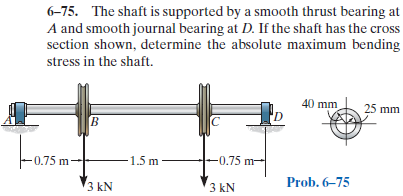

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-75P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-75P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('concentrated', 'force', -3*u.kN, 0.75*u.m);
b = b.add('concentrated', 'force', -3*u.kN, 2.25*u.m);
b = b.add('reaction', 'force', 'Rd', 3*u.m);
b.L = 3*u.m;

# section properties

Ro = 40*u.mm;
Ri = 25*u.mm;
b.I = rewrite(sympi*(Ro^4-Ri^4)/4, u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{200000000\,x\,\left(4\,x-9\,m\right)\,\left(4\,x+9\,m\right)}{3471\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }x\leq \frac{3}{4}\,m\\ \frac{150000000\,\left(16\,x^{2}-48\,x\,m+3\,m^{2}\right)}{1157\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{3}} & \text{ if }x\in \left(\frac{3}{4}\,m,\frac{9}{4}\,m\right]\\ -\frac{200000000\,\left(x-3\,m\right)\,\left(4\,x-3\,m\right)\,\left(4\,x-21\,m\right)}{3471\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }\frac{9}{4}\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{200000000\,\left(27\,m^{2}-16\,x^{2}\right)}{1157\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }x\leq \frac{3}{4}\,m\\ \frac{2400000000\,\left(2\,x-3\,m\right)}{1157\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{3}} & \text{ if }x\in \left(\frac{3}{4}\,m,\frac{9}{4}\,m\right]\\ -\frac{200000000\,\left(16\,x^{2}-96\,x\,m+117\,m^{2}\right)}{1157\,\text{E}\,\pi }\,\frac{\mathrm{kN}}{m^{4}} & \text{ if }\frac{9}{4}\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 3\,x\,\mathrm{kN} & \text{ if }x\leq \frac{3}{4}\,m\\ \frac{9}{4}\,\mathrm{kN}\,m & \text{ if }x\in \left(\frac{3}{4}\,m,\frac{9}{4}\,m\right]\\ -3\,\left(x-3\,m\right)\,\mathrm{kN} & \text{ if }\frac{9}{4}\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 3\,\mathrm{kN} & \text{ if }x\leq \frac{3}{4}\,m\\ 0 & \text{ if }x\in \left(\frac{3}{4}\,m,\frac{9}{4}\,m\right]\\ -3\,\mathrm{kN} & \text{ if }\frac{9}{4}\,m<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 3\,\mathrm{kN}\\ \mathrm{Rd} & 3\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

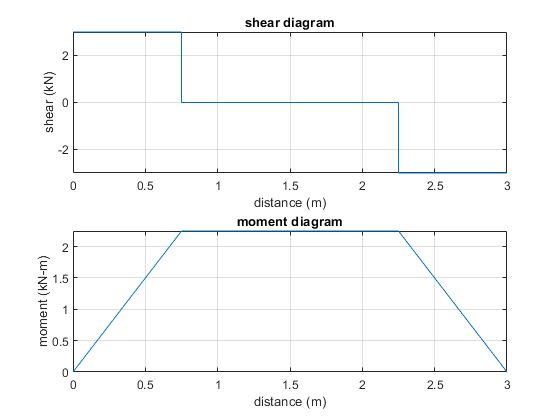

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# absolute maximum bending moment

M_max = m(1.5*u.m);
M_max_vpa = vpa(M_max) %#ok<NASGU> 

$$M\_max\_vpa = 2.25\,\mathrm{kN}\,m$$

C = Ro;
b.I = rewrite(b.I, u.mm);
sigma_max = rewrite(M_max*C/b.I, u.MPa);
sigma_max_vpa = vpa(sigma_max, 4) %#ok<NASGU> 

$$sigma\_max\_vpa = 52.82\,\mathrm{MPa}$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear M_max_vpa sigma_max_vpa;